# SAMMI Interactive Network Visualization Tool

## Authors:

Andre Schultz, Department of Bioinformatics and Computational Biology, UT MD Anderson Cancer Center, Houston, Texas, USA

Rehan Akbani, Department of Bioinformatics and Computational Biology, UT MD Anderson Cancer Center, Houston, Texas, USA

## INTRODUCTION

SAMMI loads COBRA models as force-directed, interactive networks on a web-browser. Large networks can easily be partitioned into sub-networks which can then be navigated using a series of provided functionality. Users can also load only a subset of reactions and map data as nodes and edges color and size. To familiarize yourself with SAMMI, we strongly suggest users refer to our [video tutorials](https://sammi.readthedocs.io/en/latest/videos.html).

In addition, users can temporarily or permanently remove nodes (ideal for secondary metabolites), isolate nodes, arrange nodes in specific shapes, export maps in a SAMMI specific format and PDF, and more. For a full list of interface functionalities, please refer to the [SAMMI documentation](https://sammi.readthedocs.io/en/latest/index.html). For examples of how to work with SAMMI please refer to the procedures section of this tutorial.

If you use SAMMI, please refer to the following publication:

- Schultz, A. & Akbani, R. SAMMI: a semi-automated tool for the visualization of metabolic networks. *Bioinformatics*. 36 (8), 2616–2617 (2020) 

## MATERIALS

No materials needed.

## EQUIPMENT SETUP

This SAMMI plugin requires MATLAB with a working COBRA toolbox installation, a system web-browser, and a working internet connection. If working on a remote server, X11 forwarding must be enabled or the relevant html file (index_load.html by default located in src/visualization/SAMMIM within your cobratoolbox folder) can be openned on your local machine in order to visualize the networks on a web browser. The latter can be done by mounting the remote folder on your local machine (e.g. sshfs) or by transfering the relevant files to your machine. If transferring the files you must also transfer all .js and .css files to the same folder.

SAMMI can also be run as a standalone tool on a web-browser through the SAMMI [home page](https://bioinformatics.mdanderson.org/public-software/sammi/). A [python plugin](https://sammipy.readthedocs.io/en/latest/index.html) is also available for COBRApy.

## PROCEDURE

This section includes some of the examples of how to work with the SAMMI MATLAB plugin. For the full plugin documentation and a full list of examples please refer to the [SAMMI MATLAB plugin documentation](https://sammim.readthedocs.io/en/latest/index.html). All of these examples are also available through the testSammi function.

For these examples, first make sure the COBRA toolbox is initiated. Since we will be working with models included with the toolbox, we will also retrieve the COBRA toolbox path:

%Initialize toolbox
initCobraToolbox
%Get COBRA directory
global CBTDIR;

To plot the entire model simply call the sammi function on the COBRA model. This is not advisable for medium to large models as the visualization may be too large to render.

%Load model
load([CBTDIR '/test/models/mat/ecoli_core_model.mat'])
%Plot
sammi(model)

This should automatically open the following network on your web browser:

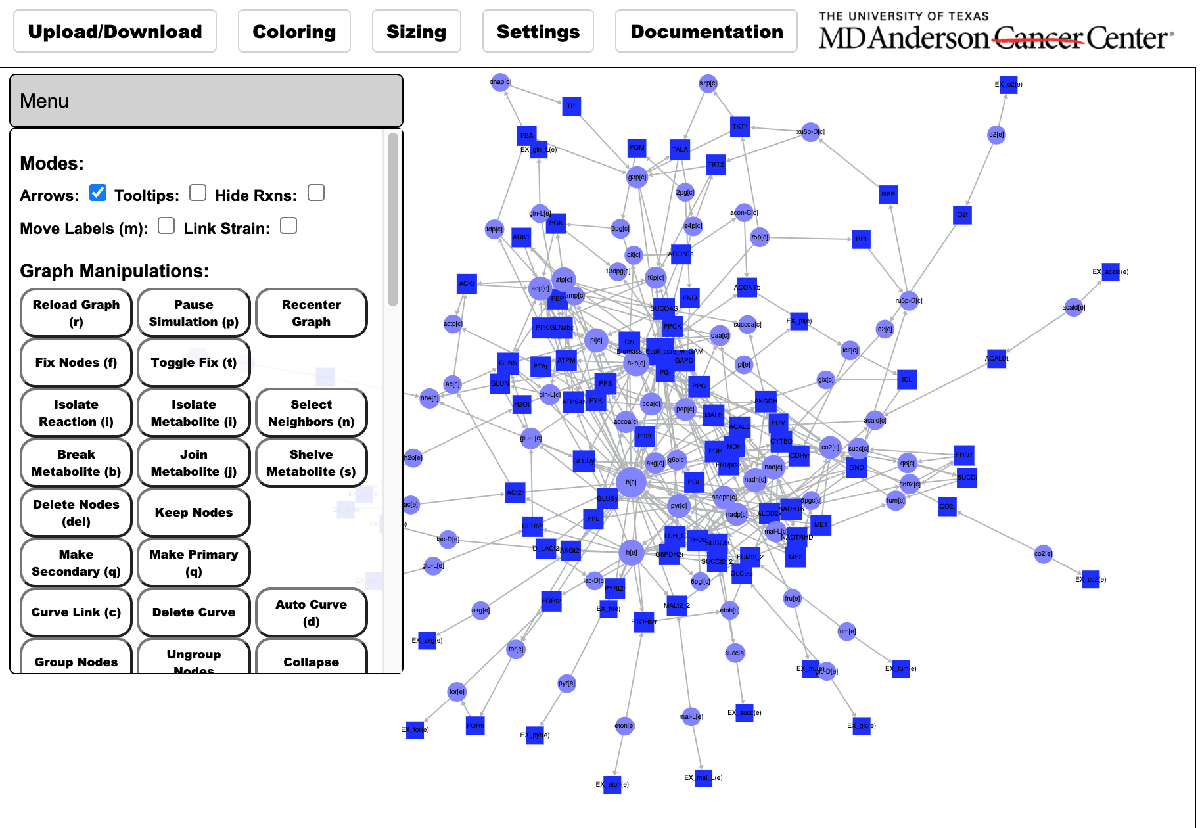

For larger models that can be too convoluted and too heavy to load in a single graph, users can define sub-graphs that can then be navigated using tools like the search and highlight functions. For this, simply pass the field you wish to use to partition the model as a second argument to the sammi function. This can be any reaction or metabolite field. The following example loads the Recon2 reconstruction (Thiele et. al.) divided into subsytems

%Load model
load([CBTDIR '/test/models/mat/Recon2.v04.mat'])
%Plot a subgraph for each subsystem
sammi(modelR204,'subSystems')

This code will load the following map on your browser, where subfields can be navigated using the drop-down menu in the floating menu window:

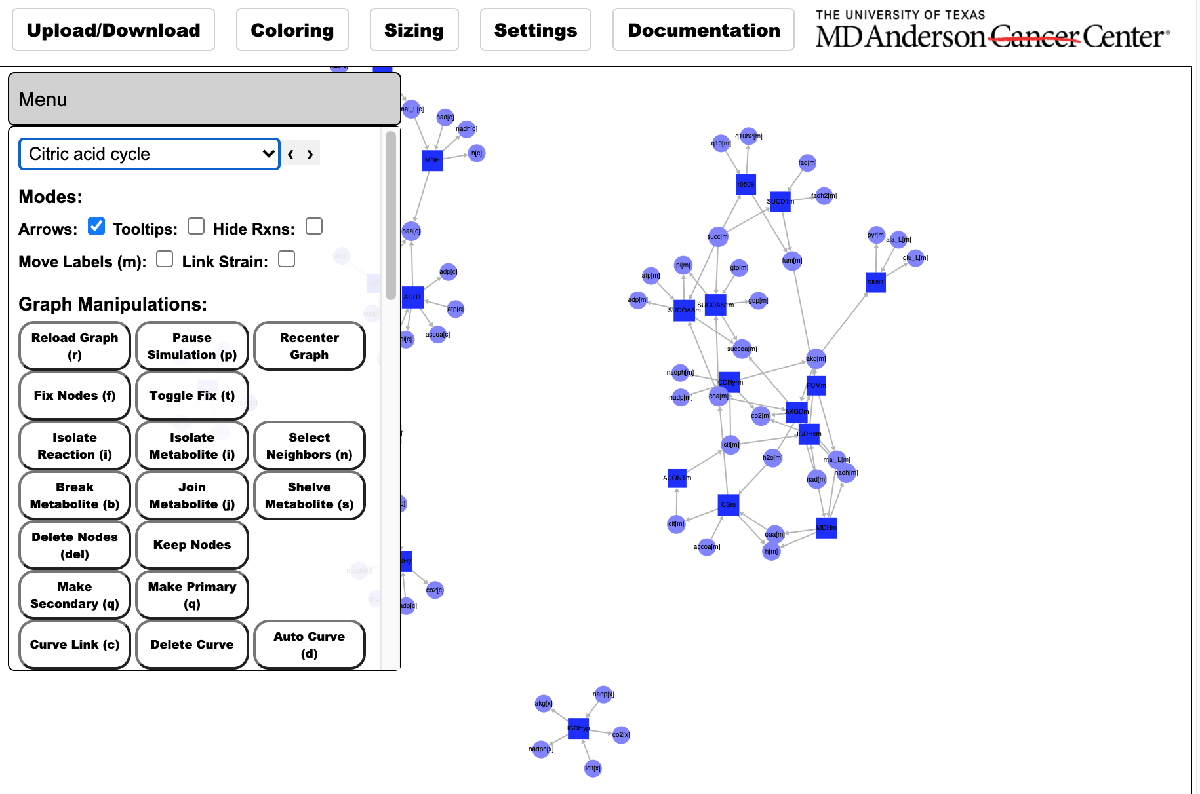

To plot only user-defined reactions and their associated data, users can define a struct with which to parse the model into subsytems, and pass that struct as a second argument to th sammi function. The following example defines three subgraphs and generates random fluxes for each reaction.

%Load model
load([CBTDIR '/test/models/mat/ecoli_core_model.mat'])
%Get reactions to plot
dat = struct;
dat(1).name = 'TCA Cycle';
dat(1).rxns = {'ACONTa';'ACONTb';'AKGDH';'CS';'FUM';'ICDHyr';'MDH';'SUCOAS'};
dat(2).name = 'Glycolysis';
dat(2).rxns = {'ENO';'FBA';'FBP';'GAPD';'PDH';'PFK';'PGI';'PGK';'PGM';'PPS';'PYK';'TPI'};
dat(3).name = 'Pentose Phosphate Pathway';
dat(3).rxns = {'G6PDH2r';'GND';'PGL';'RPE';'RPI';'TALA';'TKT1';'TKT2'};
%Add random flux
for i = 1:3; dat(i).flux = randn(length(dat(i).rxns),1); end
%Plot only desired reactions
sammi(model,dat);

The code above should yield the following graph:

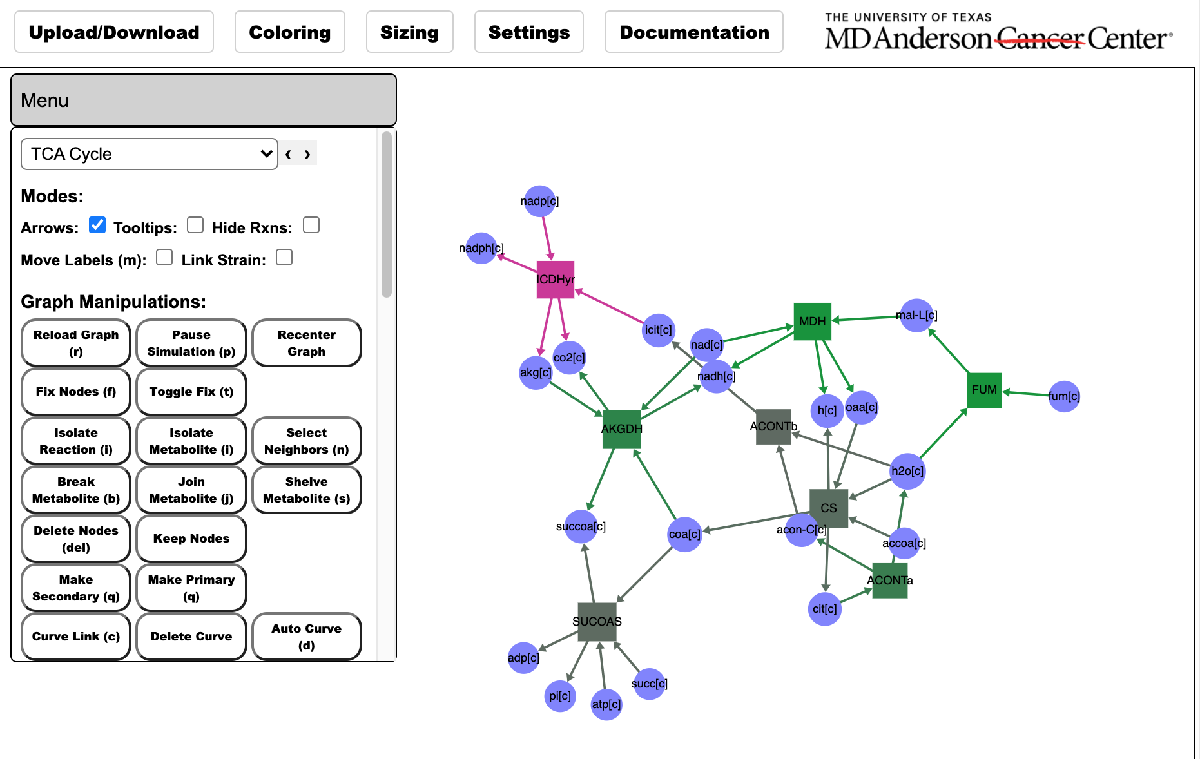

To plot multiple sets of reaction and metabolite data as other than reaction color, users can save the desired data as a data table. This data table can then be saved into a struct and passed as a third argument to the sammi function. For instance, we can load five different sets of data (here random numbers) to the e_coli core model. The following code generated these data tables with a few NaNs:

%Load model
load([CBTDIR '/test/models/mat/ecoli_core_model.mat'])
%Define number of conditions
n = 5;
%Make reaction table with random data
rxntbl = randn(length(model.rxns),n);
rxntbl(randsample(length(model.rxns)*n,floor(n*length(model.rxns)/10))) = NaN;
rxntbl = array2table(rxntbl,'VariableNames',sprintfc('condition_%d',1:n),...
    'RowNames',model.rxns);
%Make metabolites table with random data
mettbl = randn(length(model.mets),n);
mettbl(randsample(length(model.mets)*n,floor(0.5*length(model.mets)))) = NaN;
mettbl = array2table(mettbl,'VariableNames',sprintfc('condition_%d',1:n),...
    'RowNames',model.mets);

The reactions table, for instance, looks like the following:

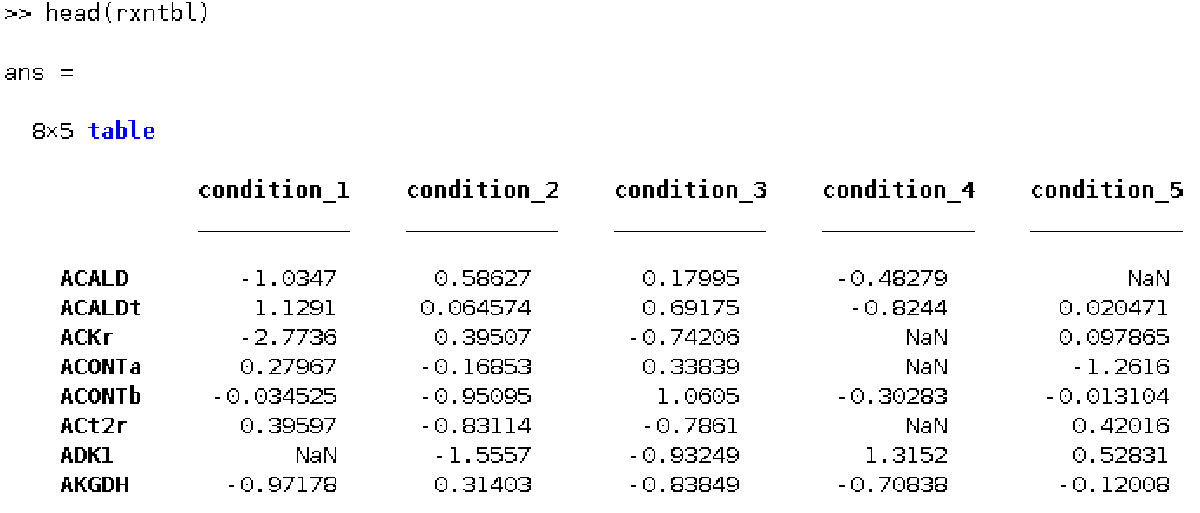

These tables can then be saved into a struct defining how the data should be mapped onto the network.

%Make struct
dat = struct;
dat(1).type = {'rxns' 'color'}; %Reaction nodes and edge color
dat(1).data = rxntbl;
dat(2).type = {'rxns' 'size'};  %Reaction nodes size
dat(2).data = rxntbl;
dat(3).type = {'mets' 'color'}; %Metabolite nodes color
dat(3).data = mettbl;
dat(4).type = {'mets' 'size'};  %Metabolite nodes size
dat(4).data = mettbl;
dat(5).type = {'links' 'size'}; %Edge thickness
dat(5).data = rxntbl;

In addition, in order to make the network less convoluted, we can shelve (temporarly remove) secondary metabolite nodes. Although this can de done through the floating menu using the "Shelve Metabolite" function (shortcut "s"), it can also be done programmatically for convenience. These metabolites can be re-introduced to the network using the "shelved metabolites" subsection of the floating window. To do so, define a list of regular expression strings into a cell array and pass that as the fourth argument to the sammi function. Any metabolite, matching any of these expressions will be shelved. For example:

%Define secondaries
secondaries = {'^h\[.\]$','^h20\[.\]$','^o2\[.\]$','^co2\[.\]$',...
    '^atp\[.\]$','^adp\[.\]$','^pi\[.\]$',...
    '^nadh\[.\]$','^nadph\[.\]$','^nad\[.\]$','^nadp\[.\]$'};

Finally, plot the network and all the data:

%Plot dividing up by subsystems
sammi(model,'subSystems',dat,secondaries)

The code above should yield the following network, where users can navigate subsystems as well as data conditions through the floating menu:

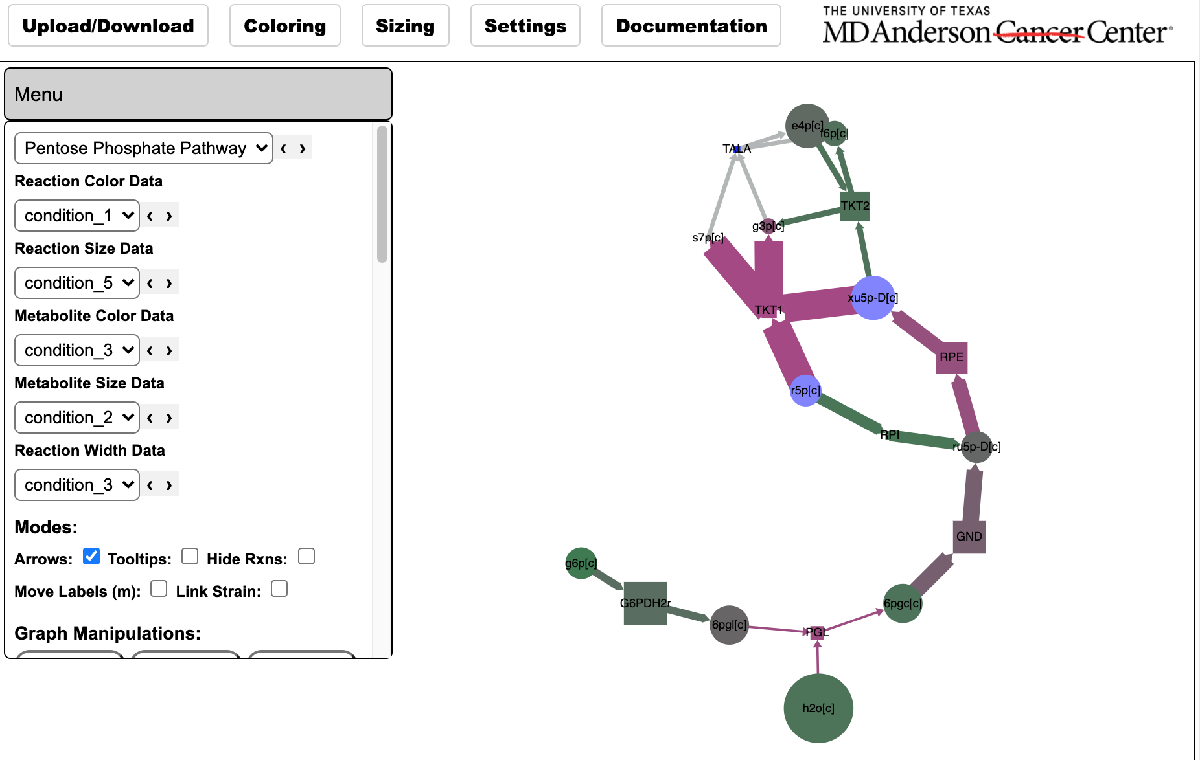

## TROUBLESHOOTING

For questions and/or bug reports please submit issue requests either to the general [SAMMI repository](https://github.com/MD-Anderson-Bioinformatics/SAMMI) or to the [MATLAB plugin repository](https://github.com/schultzdre/SAMMIM), or feel free to email Andre directly at the gmail schultzdre.

## TIMING

SAMMI should not take more than a few seconds to load even the largest models, although relative speed should depend on your internet connection and map rendering varies with network size. If your map is taking a long time to render try dividing it into subgraphs.

## Acknowledgments

The authors would like to thank our funding sources NIH/NCI and DOD. We would also like to thank Mary Rohrdanz and Chris Wakefield for their help implementing and maintaining SAMMI.

## REFERENCES

- 31, pages419–425 (2013)

- Thiele et. al. A community-driven global reconstruction of human metabolism. *Nat Biotech*. 31, 419–425 (2013)